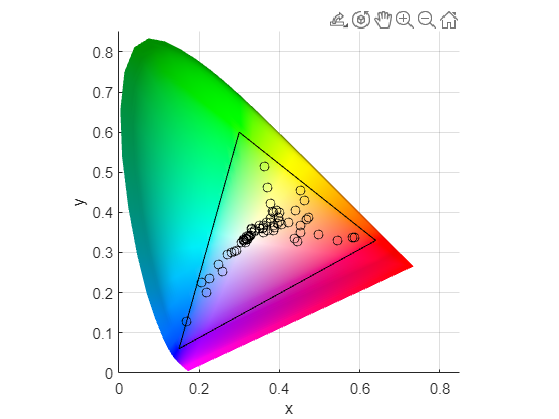

%https://se.mathworks.com/help/images/ref/plotchromaticity.html#mw_8ea535a1-aaed-41e6-b43c-e227abca6cbe

clearvars -except textures


figure
plotChromaticity("ColorSpace", "xy")
hold on

xyz_primaries = rgb2xyz([1 0 0; 0 1 0; 0 0 1]);
xyzMag = sum(xyz_primaries,2);

x_primary = xyz_primaries(:,1)./xyzMag;
y_primary = xyz_primaries(:,2)./xyzMag;

wp = whitepoint('D65');
wpMag = sum(wp,2);

x_whitepoint = wp(:,1)./wpMag;
y_whitepoint = wp(:,2)./wpMag;

%scatter(x_whitepoint,y_whitepoint,36,'black')
%scatter(x_primary,y_primary,36,'black')

plot([x_primary; x_primary],[y_primary; y_primary],'k')


%Plot the textures
for i = 1:numel(textures)
    color = textures(i).avgLAB;
    xyz_primaries  = lab2xyz(color);

    xyzMag = sum(xyz_primaries,2);
    x_primary = xyz_primaries(:,1)./xyzMag;
    y_primary = xyz_primaries(:,2)./xyzMag;

    
    scatter(x_primary,y_primary,36,'black')
    
end

hold off